% syms s t;
s = tf('s');

student_num = [3 8 1 1 3 5 4 4];
sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

rad2deg = 180/pi;
deg2rad = pi/180;

% p2 

P2_ampDataPlot(38113544);

T_r   = 0.4200*1e-3; %ms
T_p   = 0.597*1e-3; 
T_s   = 0.81*1e-3;


final_value = 2.666;
alove = final_value + final_value*0.02

alove = 2.7193

below = final_value - final_value*0.02

below = 2.6127

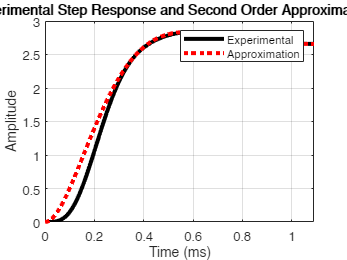

overshoot   = 2.835-final_value;
p_overshoot = overshoot/final_value*100;

zeta = sqrt(log(overshoot/final_value)^2/(pi^2+log(overshoot/final_value)^2));
beta = sqrt(1-zeta^2);
% beta_2 = -3*pi/log(p_overshoot)



% we want to find the zeta and the natural frequency so we can then
% approximate this curve as the step response of a 2nd order system
wn_ts = 4/(zeta*T_s);

wn_tp = pi/(T_p*beta);

wn_tr = (pi-atan(beta/zeta))/(beta*T_r);
xfer_s = wn_ts^2/(s^2+2*zeta*wn_ts*s+wn_ts^2)*final_value;
xfer_p = wn_tp^2/(s^2+2*zeta*wn_tp*s+wn_tp^2)*final_value;
xfer_r = wn_tr^2/(s^2+2*zeta*wn_tr*s+wn_tr^2)*final_value;

figure(1);
set(findall(gcf,'type','line'),'Color','Black');

[y_s, t_s] = step(xfer_s);
[y_p, t_p] = step(xfer_p);
[y_r, t_r] = step(xfer_r);

hold on
% plot(t_s, y_s, ':', 'LineWidth', 3, 'Color','Red')
% plot(t_p, y_p, ':', 'LineWidth', 3, 'Color','Black')
plot(t_r*1000, y_r, ':', 'LineWidth', 3, 'Color','Red')
grid on
hold off

title("Comparison of Experimental Step Response and Second Order Approximation using Settle Time")
xlabel("Time (ms)")
ylabel("Amplitude")
axis([0, 1.09, 0, 3])
legend("Experimental", "Approximation")

[num_p2, den_p2] = tfdata(xfer_s, 'v');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
P2_ampTF = tf(num_p2, den_p2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% at nominal voltage and no load, by finding the operating conditions of the motor we
% can deduce what the friction of the bearing is, as thats the only source
% of force working against the acceleration of the motor, and must balance
% the torque output otherwise the motor would continue to speed up

no_load_speed = 6260; % rpm
no_load_current = 11*1e-3; % A
torque_constant = 18*1e-3; % Nm/A

%%%%%%%%%%%%%%%%%%
P4_Bm = torque_constant * no_load_current * 2*pi/60/ no_load_speed ; % Nm / rpm  
%%%%%%%%%%%%%%%%

time_constant = (exp(1)-1)/exp(1);

%%%%%%%%%%%%%%%%%%%
P4_TCspd = no_load_speed * time_constant; % rpm
%%%%%%%%%%%%%%%%%%%%%%
TCspd = P4_TCspd * 2*pi/60 % rad/s

TCspd = 414.3839


L = 0.581*1e-3; % H
R = 19.2; % Ohms
Ye = 1/(s*L+R);

J = 1.03*1e-7; % given as 1.03 gcm^2 -> /1e-3/1e-4
B = P4_Bm;
Ym = 1/(J*s+B)*60/(2*pi);

Km = 531; % rpm/V
Km = 60/(Km*2*pi); % Nm/rad*A




% given
JG = sn_A*75*1e-10;
JF = sn_B*25*1e-10;
JL = 60*1e-10;

BG = sn_C*20*1e-7; % updated to 10x in p6
BF = sn_D*400*1e-10;
BL = 500*1e-10;

KG = sn_E*3000*1e-4;
KF = sn_F*1800*1e-4;
KL = 2500*1e-4;

JM = 1.03*1e-7; % datasheet gave g*cm^2, converted to kg*m^2
BM = P4_Bm; % Nm / rad/s
tauM = 1;


% convert these to the fucking electric ones kms

CG = JG;
CF = JF;
CL = JL;

RG = 1/BG;
RF = 1/BF;
RL = 1/BL;
RM = 1/BM;

LG = 1/KG;
LF = 1/KF;
LL = 1/KL;

CM = JM;
IM = tauM;

mat11 = CM*s+1/(LG*s)+1/RG+1/RM;
mat22 = CG*s+1/RG+1/(LG*s)+1/RF+1/(LF*s);
mat33 = CF*s+CL*s+1/RF+1/(LF*s)+1/(LL*s)+1/RL;

mat12 = -1/RG-1/(LG*s);
mat13 = 0;

mat23 = -1/RF-1/(LF*s);

Y = [mat11, mat12, mat13;  
     mat12, mat22, mat23; 
     mat13, mat23, mat33] 

Y =
 
  From input 1 to output...
       2.641e-08 s^2 + 5.642e-06 s + 1
   1:  -------------------------------
                  0.2564 s
 
       -5.641e-06 s - 1
   2:  ----------------
           0.2564 s
 
   3:  0
 
  From input 2 to output...
       -5.641e-06 s - 1
   1:  ----------------
           0.2564 s
 
       9.259e-09 s^3 + 2.131e-06 s^2 + 0.6268 s
   2:  ----------------------------------------
                     0.09497 s^2
 
       -1.63e-07 s - 1
   3:  ---------------
          0.3704 s
 
  From input 3 to output...
   1:  0
 
       -1.63e-07 s - 1
   2:  ---------------
          0.3704 s
 
       7.556e-08 s^3 + 7.259e-07 s^2 + 4.37 s
   3:  --------------------------------------
                     1.481 s^2
 
Continuous-time transfer function.



     

Z = inv(Y);

I = [IM; 0; 0];

V = Z*I;
Vm = V(1);
VG = V(2);
VF = V(3);
VL = VF;

Ym_update = minreal(Vm/IM);

[num, den] = tfdata(Ym_update,'v');
[y, t] = step(Ym_update);

%%%%%%%%%%%%%
P4_Ym = minreal(tf(num, den), 1e-2);
%%%%%%%%%%%%%


% plot(t, y, ".", 'LineWidth', 0.1, 'Color','Blue')

% integrate to get angles from angular vel (voltages)

stall_torque = 11.2*(1e-3) % datasheet gives milli Nm

stall_torque = 0.0112

% I_stall = [stall_torque; 0; 0];
% V_stall = Z*I_stall;
%
% Vm_stall = V(1);
% VG_stall = V(2);
% VF_stall = V(3);
% VL_stall = VF_stall;

wM = Vm;

opt = stepDataOptions('StepAmplitude',stall_torque);
xfer_M = minreal(wM/s);

% hold off
% 
% [num_M, den_M] = tfdata(xfer_M,'v');
% [y_M, t_M] = step(xfer_M, opt);
% plot(t_M, y_M*180/pi, '.', 'LineWidth', 0.01, 'Color','Red')

% grid on
% xlabel("Time (sec)")
% ylabel("All Angles (deg)")
% axis([0, 24, 0, 1.2])

% hold on
wL = VL;

Y_l = minreal(wL);

[num_L, den_L] = tfdata(Y_l,'v');
% [y_L, t_L] = step(Y_l, opt);
% plot(t_L, y_L*180/pi, '.', 'LineWidth', 0.01, 'Color','Blue')

%%%%%%%%%%%%%%%
P4_Gf = tf(num_L, den_L);
%%%%%%%%%%%%%%%

% grid on
% title("Step Response at Half Stall Torque of Motor Angle and Load Angle")
% legend("Motor Angle", "Load Angle")

% part 5

% making state matrix using mechanical 

% xhat = thetam thetag thetal wm wg wl

P5_A = [0, 0, 0, 1, 0 ,0;    % thetam
        0, 0, 0, 0, 1 ,0;
        0, 0, 0, 0, 0 ,1;  
        -KG/JM, KG/JM, 0, -(BG+BM)/JM, BG/JM, 0;   % wm
        KG/JG, -(KF+KG)/JG, KF/JG, BG/JG, -(BF+BG)/JG, BF/JG;
        0, KF/(JL+JF), -(KL+KF)/(JL+JF), 0, BF/(JL+JF), -(BF+BL)/(JL+JF)];

P5_B = [0, 0, 0, 1/JM, 0, 0].'; 

%yhat = [thetam thetal wm taukg taukf taukl]

% c will be 6x6
% P5_C = [1, 0, 0, 0, 0, 0;
%         0, 0, 1, 0, 0, 0;
%         0, 0, 0, 1, 0, 0;
%         -KG, KG, 0, 0, 0, 0;
%         0, -KF, KF, 0, 0, 0;
%         0, 0, -KL, 0, 0, 0;
%        ];

P5_C = [1, 0, 0, 0, 0, 0;
        0, 0, 1, 0, 0, 0;
        0, 0, 0, 1, 0, 0;
        KG, -KG, 0, 0, 0, 0;
        0, KF, -KF, 0, 0, 0;
        0, 0, KL, 0, 0, 0;
       ];



P5_D = [0, 0, 0, 0, 0, 0].';

stall_torque = 11.2*1e-3;
opt = stepDataOptions('StepAmplitude',stall_torque/2);



ss_system = ss(P5_A, P5_B, P5_C, P5_D);
[ss_responses, ss_t] = step(ss_system, opt);
thetaM = ss_responses(:,1);
thetaL = ss_responses(:,2);
omegaM = ss_responses(:,3);
tauKg  = ss_responses(:,4);
tauKf  = ss_responses(:,5);
tauKl  = ss_responses(:,6);

hold off

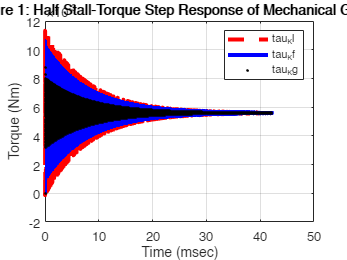


plot(ss_t, tauKl, '--', 'LineWidth', 3, 'Color','Red');
hold on
plot(ss_t, tauKf, '-', 'LineWidth', 3, 'Color','Blue');
plot(ss_t, tauKg, '.', 'LineWidth', 3, 'Color','Black');

grid on
title("Figure 1: Half Stall-Torque Step Response of Mechanical Gripper")
xlabel("Time (msec)")
ylabel("Torque (Nm)")
legend("tau_Kl","tau_Kf", "tau_Kg")
axis([0, 50, -2*1e-3, 12*1e-3])

hold off

% need to add the full system model (electro-mechanical system)

% from datasheet
Vin = 6;

% Terminal inductance and resistance
L = 0.581*1e-3; % H
R = 19.2; % Ohms

Km = 531; % rpm/V
Km = 60/(Km*2*pi); % Nm/rad*A

P5_A2 = [-R/L, 0, 0, 0, -Km/L, 0, 0; % V
         0, 0, 0, 0, 1, 0 ,0;    % thetam
         0, 0, 0, 0, 0, 1 ,0; % 
         0, 0, 0, 0, 0, 0 ,1;  
         Km/JM, -KG/JM, KG/JM, 0, -(BG+BM)/JM, BG/JM, 0;   % wm
         0, KG/JG, -(KF+KG)/JG, KF/JG, BG/JG, -(BF+BG)/JG, BF/JG;
         0, 0, KF/(JL+JF), -(KL+KF)/(JL+JF), 0, BF/(JL+JF), -(BF+BL)/(JL+JF)];

P5_B2 = [1/L, 0, 0, 0, 0, 0, 0].'; 

%yhat = [thetam thetal wm taukg taukf taukl]


P5_C2 = [0, 1, 0, 0, 0, 0, 0;
        0, 0, 0, 1, 0, 0, 0;
        0, 0, 0, 0, 1, 0, 0;
        0, -KG, KG, 0, 0, 0, 0;
        0, 0, -KF, KF, 0, 0, 0;
        0, 0, 0, -KL, 0, 0, 0;
       ];



P5_D2 = [0, 0, 0, 0, 0, 0].';

opt_2 = stepDataOptions('StepAmplitude',6);
ss_system_2 = ss(P5_A2, P5_B2, P5_C2, P5_D2);
[ss_responses_2, ss_t_2] = step(ss_system_2, opt_2);
thetaM_2 = ss_responses_2(:,1);
thetaL_2 = ss_responses_2(:,2);
omegaM_2 = ss_responses_2(:,3);
tauKg_2  = ss_responses_2(:,4);
tauKf_2  = ss_responses_2(:,5);
tauKl_2  = ss_responses_2(:,6);


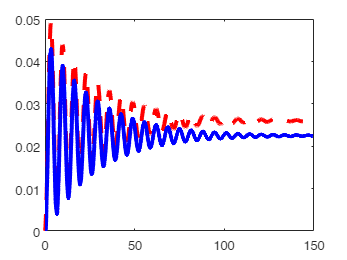

plot(ss_t_2*1000, thetaM_2, '--', 'LineWidth', 3, 'Color','Red');
hold on
plot(ss_t_2*1000, thetaL_2, '-', 'LineWidth', 3, 'Color','Blue');
hold off

%%%%%%%%%%%%%%% P 6 %%%%%%%%%%%%%%%%%%
Kp = 1; %initializing, gets set to Ku/5 later
sensor = 1;
CF = 10*sn_F;
mcu_dynamics = 2*CF/(s+2*CF)

mcu_dynamics =
 
    300
  -------
  s + 300
 
Continuous-time transfer function.




%%%%%%%%%% Loop Gain %%%%%%%%%%%%%%%%%%%
[ss_tf_num, ss_tf_den] = ss2tf(P5_A2, P5_B2, P5_C2, P5_D2);

motor_tf = tf(ss_tf_num(1,:), ss_tf_den);

P6_G = Kp*P2_ampTF*motor_tf*rad2deg

P6_G =
 
                                                                                            
                          2.571e18 s^4 + 6.165e20 s^3 + 3.228e26 s^2 + 3.468e28 s + 6.299e33
                                                                                            
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  s^9 + 4.338e04 s^8 + 5.707e08 s^7 + 9.125e12 s^6 + 7.139e16 s^5 + 5.659e20 s^4 + 2.293e24 s^3 + 1.09e28 s^2       
                                                                                                                    
                                                                                             + 2.764e30 s + 9.515e33
                                                                                                                    
 
Continuo

G = P6_G

G =
 
                                                                                            
                          2.571e18 s^4 + 6.165e20 s^3 + 3.228e26 s^2 + 3.468e28 s + 6.299e33
                                                                                            
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  s^9 + 4.338e04 s^8 + 5.707e08 s^7 + 9.125e12 s^6 + 7.139e16 s^5 + 5.659e20 s^4 + 2.293e24 s^3 + 1.09e28 s^2       
                                                                                                                    
                                                                                             + 2.764e30 s + 9.515e33
                                                                                                                    
 
Continuous-

P6_H =  sensor*mcu_dynamics

P6_H =
 
    300
  -------
  s + 300
 
Continuous-time transfer function.



H = P6_H

H =
 
    300
  -------
  s + 300
 
Continuous-time transfer function.




P6_TF = P6_G/(1+P6_G*P6_H)

P6_TF =
 
                                                                                                                     
   2.571e18 s^14 + 1.129e23 s^13 + 1.851e27 s^12 + 3.84e31 s^11 + 3.926e35 s^10 + 4.852e39 s^9 + 3.463e43 s^8        
                                                                                                                     
           + 2.82e47 s^7 + 1.305e51 s^6 + 7.555e54 s^5 + 1.788e58 s^4 + 7.652e61 s^3 + 3.928e64 s^2 + 6.525e67 s     
                                                                                                                     
                                                                                                           + 1.798e70
                                                                                                                     
  --------------------------------------------------------------------------------------------------------------------
                                             


hold off

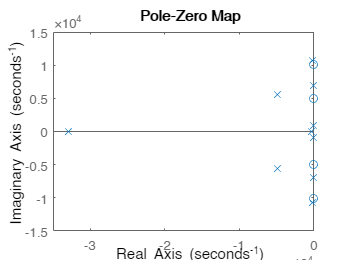

pzmap(P6_G*P6_H);

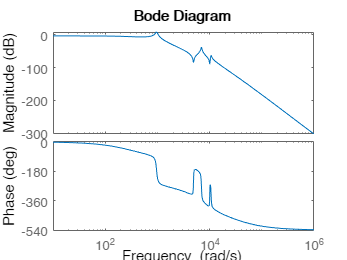

bode(P6_G*P6_H);


%%% reduced %%
P6_GH = minreal(P6_G*P6_H, 10);
bode(P6_GH);
title("Bode Diagram of OLTF with minreal() tolerance of 10")

P6_Ku = round(margin(P6_GH), 3);

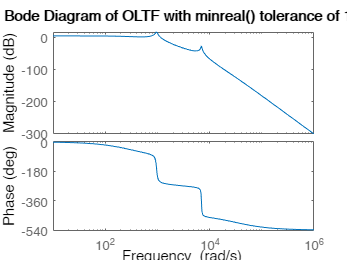


hold off

ten_deg = stepDataOptions('StepAmplitude',10);

tf_ku2 = P6_Ku/2*P6_G/(1+P6_Ku/2*P6_G*P6_H); % Ku/2
[ku2, t2] = step(tf_ku2, ten_deg);

tf_ku5 = P6_Ku/5*P6_G/(1+P6_Ku/5*P6_G*P6_H); % Ku/5
[ku5, t5] = step(tf_ku5, ten_deg);

tf_ku10 = P6_Ku/10*P6_G/(1+P6_Ku*P6_G/10*P6_H); % Ku/10
[ku10, t10] = step(tf_ku10, ten_deg);

% 
% figure(69);
% plot(t10, ku2)
% hold on 
% grid on
% plot(t10, ku5)
% plot(t10, ku10)
% legend("Gain = Ku/2", "Gain = Ku/5", "Gain = Ku/10")
hold off

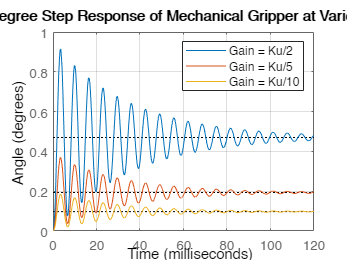

tf_ku2 = chgTimeUnit(tf_ku2, "milliseconds");
tf_ku5 = chgTimeUnit(tf_ku5, "milliseconds");
tf_ku10 = chgTimeUnit(tf_ku10, "milliseconds");


figure(69);
step(tf_ku2, ten_deg);
hold on 
grid on
step(tf_ku5, ten_deg);
step(tf_ku10, ten_deg);
legend("Gain = Ku/2", "Gain = Ku/5", "Gain = Ku/10")
axis([0, 120, 0, 1])
title("10 Degree Step Response of Mechanical Gripper at Various Gains")
ylabel("Angle (degrees)")
hold off

hold off

Kp = P6_Ku/5

Kp = 0.0298

% fig 1 proj 7
rla(P6_GH)

ans = 	1.0e+06 *

  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0328 + 0.0000i  -0.0328 + 0.0000i  -0.0328 + 0.0000i  -0.0327 + 0.0000i  -0.0325 + 0.0000i  -0.0323 + 0.0000i
  -0.0001 + 0.0070i  -0.0001 + 

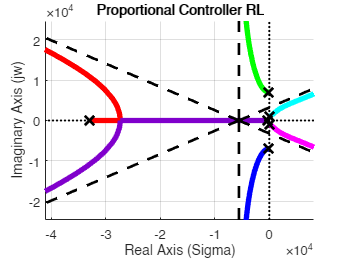

title("Proportional Controller RL")


p = 2*CF;
z = CF;

KD = (p-z)/(p*z);
FDD = s*p/(s+p);

D = 1 + KD*FDD

D =
 
  2 s + 300
  ---------
   s + 300
 
Continuous-time transfer function.




P7_D = D;

untuned_lead_oltf = D*P6_G*P6_H

untuned_lead_oltf =
 
                                                                                                   
                  1.543e21 s^5 + 6.013e23 s^4 + 1.937e29 s^3 + 4.986e31 s^2 + 3.782e36 s + 5.669e38
                                                                                                   
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  s^11 + 4.398e04 s^10 + 5.968e08 s^9 + 9.472e12 s^8 + 7.692e16 s^7 + 6.095e20 s^6 + 2.639e24 s^5 + 1.232e28 s^4    
                                                                                                                    
                                                               + 9.509e30 s^3 + 1.215e34 s^2 + 5.958e36 s + 8.564e38
                                                                                             

P7_Ku = margin(untuned_lead_oltf);


rla(untuned_lead_oltf)

ans = 	1.0e+06 *

  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0329 + 0.0000i  -0.0328 + 0.0000i  -0.0328 + 0.0000i  -0.0327 + 0.0000i  -0.0327 + 0.0000i
  -0.0002 + 0.0107i  -0.0002 + 

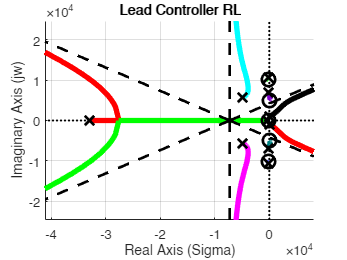

title("Lead Controller RL")

prop_ctrl_tf = minreal(P6_Ku/2*G/(1+P6_Ku/2*G*H))

prop_ctrl_tf =
 
                                                                                                                       
  1.916e17 s^10 + 6.507e21 s^9 + 6.21e25 s^8 + 1.865e30 s^7 + 7.016e33 s^6 + 1.83e38 s^5 + 3.268e41 s^4 + 7.019e45 s^3 
                                                                                                                       
                                                                               + 5.782e48 s^2 + 8.678e52 s + 2.57e55   
                                                                                                                       
  ---------------------------------------------------------------------------------------------------------------------
                                                                                                                     
   s^15 + 7.711e04 s^14 + 2.224e09 s^13 + 4.208e13 s^12 + 7.325e17 s^11 + 8.372e21 s^10 + 9.757e25 s^9 + 7.7e29 s^8  
                           

lead_ctrl_tf = minreal(P7_Ku/2*G*D/(1+P7_Ku/2*D*G*H));

aa = P6_Ku/2;
bb = P7_Ku/2;

hold off

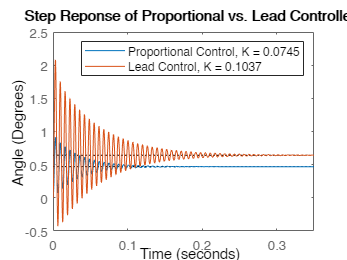

step(prop_ctrl_tf, ten_deg);
hold on 
step(lead_ctrl_tf, ten_deg);
title("Step Reponse of Proportional vs. Lead Controller")
legend("Proportional Control, K = 0.0745", "Lead Control, K = 0.1037")
ylabel("Angle (Degrees)")
hold off


[lead_y, lead_t] = step(lead_ctrl_tf, ten_deg);
[prop_y, prop_t] = step(prop_ctrl_tf, ten_deg);
ss_prop = prop_y(end)

ss_prop = 0.4700

err_test = abs(lead_y(end)-ss_prop)

err_test = 0.1783

what = 0;
min = 99;
for K = 0.005:0.005:P7_Ku
    
    loop = K*G*D/(1+K*D*G*H);
    [y_loop, t_loop] = step(loop, ten_deg);
    err = abs(y_loop(end)-ss_prop);
    if err < min
        P7_K = K;
        min = err;
    end
end


hold off

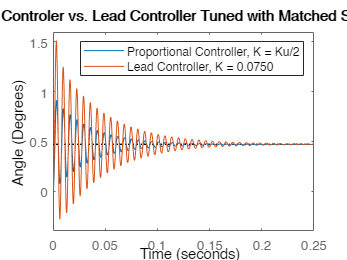

step(prop_ctrl_tf, ten_deg);
hold on
step(P7_K*G*D/(1+P7_K*D*G*H), ten_deg);
title("Proportional Controler vs. Lead Controller Tuned with Matched Steady State Error")
legend("Proportional Controller, K = Ku/2", "Lead Controller, K = 0.0750")
ylabel("Angle (Degrees)")
hold off

% proj 8
% make lag dynamics, pole at 0, start with z cancelling out 2cf

z_lag = 2*CF;
D_lag = 1/z_lag*(s+z_lag)/s;
P8_Dcf = D_lag;
P8_Ku = margin(P8_Dcf*G*H)

P8_Ku = 110.1965

guh = P8_Ku/2

guh = 55.0983

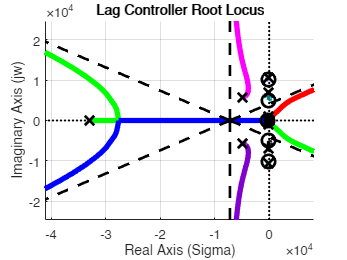

rla(P8_Dcf*G*H);
title("Lag Controller Root Locus")


lag_tf_2cf = P8_Ku/2*P8_Dcf*G/(1+P8_Ku/2*P8_Dcf*G*H);

hold off

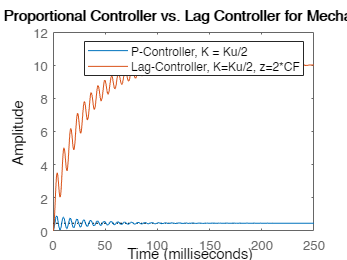

step(tf_ku2, ten_deg);
hold on
step(lag_tf_2cf, ten_deg);
title("Untuned Proportional Controller vs. Lag Controller for Mechanical Gripper")
legend("P-Controller, K = Ku/2", "Lag-Controller, K=Ku/2, z=2*CF")
hold off

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


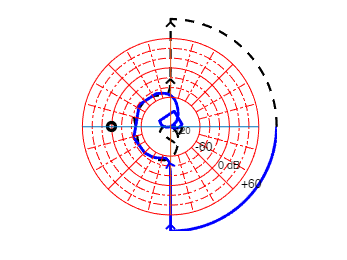

% nyq for fun
nyqlog(P8_Dcf*G*H);

[Gm,Pm,Wcg,Wcp] = margin(P8_Dcf*G*H);

z_lag_2 = Wcg/10;
D_lag_2 = 1/z_lag_2*(s+z_lag_2)/s;

[Gm,Pm,Wcg,Wcp] = margin(D_lag_2*G*H);

z_lag_3 = Wcg/10;
D_lag_3 = 1/z_lag_3*(s+z_lag_3)/s;

[Gm,Pm,Wcg,Wcp] = margin(D_lag_3*G*H);

z_lag_4 = Wcg/10;
D_lag_4 = 1/z_lag_4*(s+z_lag_4)/s;

P8_z = z_lag_4

P8_z = 96.4528

P8_D = 1/P8_z*(s+P8_z)/s

P8_D =
 
  0.01037 s + 1
  -------------
        s
 
Continuous-time transfer function.



Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


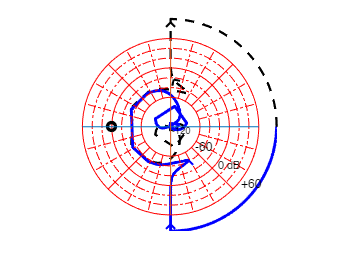

% required plot
nyqlog(P8_D*G*H)

% find gain for 0 overshoot

Ku_lag = margin(P8_D*G*H)

Ku_lag = 36.7356

for K = 0:1:Ku_lag
    cltf_loop = K*P8_D*G/(1+K*P8_D*G*H);
    [y_loop,t_loop]=step(cltf_loop,ten_deg);

    if max(y_loop) <= 10
        K_no_overshoot = K
    end
end

K_no_overshoot = 0

K_no_overshoot = 1

K_no_overshoot = 2

K_no_overshoot = 3

K_no_overshoot = 4

K_no_overshoot = 5

K_no_overshoot = 6

K_no_overshoot = 7

K_no_overshoot = 8

K_no_overshoot = 9

K_no_overshoot = 10

K_no_overshoot = 11

K_no_overshoot = 12

K_no_overshoot = 13

K_no_overshoot = 14

K_no_overshoot = 15

K_no_overshoot = 16

K_no_overshoot = 17

K_no_overshoot = 18

K_no_overshoot = 19

K_no_overshoot = 20

K_no_overshoot = 21

K_no_overshoot = 22

K_no_overshoot = 23

K_no_overshoot = 24

K_no_overshoot = 25


P8_K = K_no_overshoot

P8_K = 25

lag_cltf_no_overshoot = K_no_overshoot*P8_D*G/(1+K_no_overshoot*P8_D*G*H)

lag_cltf_no_overshoot =
 
                                                                                                                     
   6.665e17 s^16 + 2.933e22 s^15 + 4.825e26 s^14 + 9.999e30 s^13 + 1.027e35 s^12 + 1.268e39 s^11 + 9.096e42 s^10     
                                                                                                                     
           + 7.396e46 s^9 + 3.453e50 s^8 + 1.991e54 s^7 + 4.823e57 s^6 + 2.028e61 s^5 + 1.21e64 s^4 + 1.79e67 s^3    
                                                                                                                     
                                                                                          + 6.292e69 s^2 + 4.495e71 s
                                                                                                                     
  ---------------------------------------------------------------------------------------------------------------------
                            


hold off

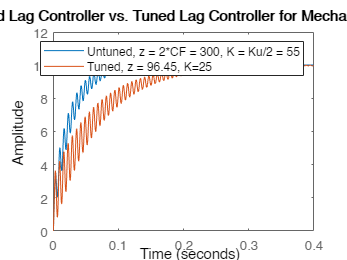

step(lag_tf_2cf, ten_deg)
hold on
step(lag_cltf_no_overshoot,ten_deg)
title("Untuned Lag Controller vs. Tuned Lag Controller for Mechanical Gripper")
legend("Untuned, z = 2*CF = 300, K = Ku/2 = 55", "Tuned, z = 96.45, K=25")
hold off

% proj 9 
% get starting z from P controller as starting point
[Gm,Pm,PxO,Wcp] = margin(1*G*H)

Gm = 0.3873

Pm = -60.0928

PxO = 968.0308

Wcp = 1.0392e+03

z_p = Wcg/10;
p = 2*CF

p = 300


% put both zeros of Lead-Lag dyanmics here to start.
% keep K as 1 for now.
K = 1;
D = K*p/(z_p*z_p)*(s+z_p)*(s+z_p)/(s*(s+p));

% interate (based)
[Gm, Pm, PxO, Wcp] = margin(D*G*H);
z_ll = PxO/10

z_ll = 97.1694


D = K*p/(z_ll*z_ll)*(s+z_ll)*(s+z_ll)/(s*(s+p));

[Gm, Pm, PxO, Wcp] = margin(D*G*H)

Gm = 12.9112

Pm = 90.5170

PxO = 971.6405

Wcp = 0.6620

z_ll = PxO/10

z_ll = 97.1641


D = K*p/(z_ll*z_ll)*(s+z_ll)*(s+z_ll)/(s*(s+p));

[Gm, Pm, PxO, Wcp] = margin(D*G*H)

Gm = 12.9098

Pm = 90.5170

PxO = 971.6409

Wcp = 0.6620

z_ll = PxO/10

z_ll = 97.1641


D = K*p/(z_ll*z_ll)*(s+z_ll)*(s+z_ll)/(s*(s+p));

% call that good
%%%%%%%%%%%
P9_z = z_ll

P9_z = 97.1641

P9_D = D

P9_D =
 
  0.03178 s^2 + 6.175 s + 300
  ---------------------------
          s^2 + 300 s
 
Continuous-time transfer function.



P9_K = margin(P9_D*G*H)

P9_K = 12.9098

%%%%%%%%%%%%%%

nyqlog(P9_D*G*H)

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


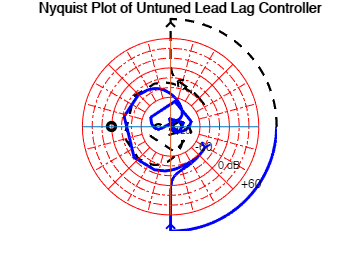

title("Nyquist Plot of Untuned Lead Lag Controller")

rla(P9_D*G*H)

ans = 	1.0e+06 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i
  -0.0329 + 0.0000i  -0.0329 + 

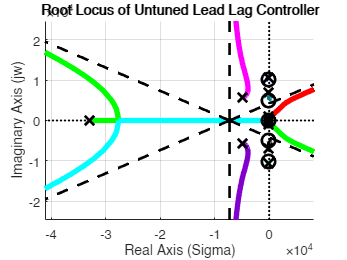

title("Root Locus of Untuned Lead Lag Controller")

% heuristic 1, only adjust K and zs. 
% needs NO overshoot, having minimum settling time is optimal
% fuck it just do this randomly no cap
hold off

K_h1 = margin(P9_D*G*H)/2

K_h1 = 6.4549

cltf_untuned = closed_loop(K_h1,P9_D,G,H)

cltf_untuned =
 
                                                                                                                      
   5.274e17 s^18 + 2.342e22 s^17 + 3.911e26 s^16 + 8.066e30 s^15 + 8.445e34 s^14 + 1.036e39 s^13 + 7.6e42 s^12        
                                                                                                                      
           + 6.143e46 s^11 + 2.968e50 s^10 + 1.686e54 s^9 + 4.451e57 s^8 + 1.761e61 s^7 + 1.607e64 s^6 + 1.844e67 s^5 
                                                                                                                      
                                                            + 1.089e70 s^4 + 2.753e72 s^3 + 2.877e74 s^2 + 1.045e76 s 
                                                                                                                      
  ----------------------------------------------------------------------------------------------------------------------
                             

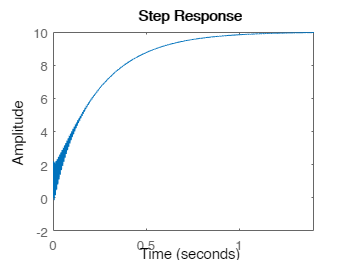

step(cltf_untuned, ten_deg)
hold off

real = 90

real = 90

img = 20

img = 20

Katio = 0.7

Katio = 0.7000


z1 = real + img*1i;
z2 = real - img*1i;

D = ll_dynamics(p, z1, z2);

Ku = margin(D*G*H);
cltf_h1 = closed_loop(Ku*Katio,D,G,H);

hold off

step(cltf_h1, ten_deg);
[y,t] = step(cltf_h1, ten_deg);
max(y)

ans = 9.9812

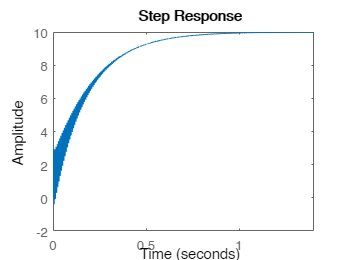

hold on
% step(last, ten_deg);
% legend("this time", "last time")
hold off


%%%%%%%%%%%%%%%%%
P9_K1 = Ku*Katio;
P9_z1 = [-real + img*1i, -real -img*1i];
%%%%%%%%%%%%%%%%%%

% build up more verbose lead lag dynamics
K_0 = Ku*Katio

K_0 = 8.1837

Kp_0 = (z1+z2)/(z1*z2)-1/p

Kp_0 = 0.0178

Ki_0 = 1

Ki_0 = 1

Kd_0 = 1/(z1*z2)-(z1+z2)/(p*(z1*z2))+1/(p*p)

Kd_0 = 5.8170e-05


K = 13

K = 13

Kp = 0.0141

Kp = 0.0141

Ki = 0.944

Ki = 0.9440

Kd = 0.0000405

Kd = 4.0500e-05


D = (Kp+Ki/s+Kd*p*s/(p+s))

D =
 
  0.02625 s^2 + 5.174 s + 283.2
  -----------------------------
           s^2 + 300 s
 
Continuous-time transfer function.




hold off

cltf = closed_loop(K,D,G,H)

cltf =
 
                                                                                                                      
    8.775e17 s^18 + 3.897e22 s^17 + 6.508e26 s^16 + 1.342e31 s^15 + 1.405e35 s^14 + 1.723e39 s^13 + 1.265e43 s^12     
                                                                                                                      
            + 1.022e47 s^11 + 4.94e50 s^10 + 2.806e54 s^9 + 7.414e57 s^8 + 2.933e61 s^7 + 2.682e64 s^6 + 3.078e67 s^5 
                                                                                                                      
                                                              + 1.823e70 s^4 + 4.65e72 s^3 + 5.011e74 s^2 + 1.986e76 s
                                                                                                                      
  ----------------------------------------------------------------------------------------------------------------------
                                     

[y,t] = step(cltf, ten_deg);
max(y)

ans = 9.9981

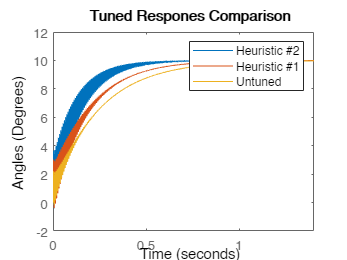


step(cltf, ten_deg)
hold on
step(cltf_h1, ten_deg)
step(cltf_untuned, ten_deg)
title("Tuned Respones Comparison")
legend("Heuristic #2", "Heuristic #1", "Untuned")
ylabel("Angles (Degrees)")
hold off



P9_K2 = 13

P9_K2 = 13

P9_Kp2 = 0.0141

P9_Kp2 = 0.0141

P9_Ki2 = 0.944

P9_Ki2 = 0.9440

P9_Kd2 = 0.0000405

P9_Kd2 = 4.0500e-05


% zeros = get_zeros(p, P9_Kp2, P9_Ki2, P9_Kd2)

a = 1;
b = (Kp*p+Ki)/(Kp+Kd*p);
c = (Ki*p)/(Kp+Kd*p);

P9_z2 = roots([a, b, c]);